clear all
close
clc

% Global constants

%global cw ca A K mpunkt_quer F_quer tc alpha lrampe r0

% Basic Design Data of Rocket

m1=10000 % [kg]

m1 = 10000

m0=80

m0 = 80

cw=0.4

cw = 0.4000

ca=0.

ca = 0

alpha=0.

alpha = 0

lrampe=10.

lrampe = 10

D=0.2

D = 0.2000

A=D^2*pi/4

A = 0.0314


% Genereric Constants

r0=6371000

r0 = 6371000

%rho=1.225
K=3.9658e14

K = 3.9658e+14

g0=9.81

g0 = 9.8100


% Motor Data

m8=26.

m8 = 26

Is=1700.

Is = 1700

tc=15.

tc = 15

mpunkt_quer=m8/tc

mpunkt_quer = 1.7333

Itot=m8*Is

Itot = 44200

F_quer=Itot/tc

F_quer = 2.9467e+03


% Calculated Rocket Data

mc=m0-m8

mc = 54

R=m0/mc

R = 1.4815


% Numerical solution
gamma=80*pi/180

gamma = 1.3963


c = [1 45] ;
tspan = [0 5];
y0 = [0 r0 m0 gamma 0];
[T,Y] = ode45(@(t,y) ha2_engine(t,y,c), tspan, y0);

% Calculate accelerations as derivatives from velocities
    deltav=diff(Y(:,1));
    deltat=diff(T);
    lt=length(T)

lt = 69

    for j=1 : lt-1
        acc(j)=deltav(j)/deltat(j);
    end
    acc(lt)=acc(lt-1)

acc =    27.2113   27.2113   27.2113   27.2113   27.2113   27.2113   27.2113   27.2113   27.2113   27.2114   27.2114   27.2115   27.2116   27.2118   27.2119   27.2121   27.2127   27.2136   27.2145   27.2154   27.2182   27.2228   27.2274   27.2320   27.2457   27.2686   27.2913   27.3140   27.3739   27.4699   27.5642   27.6566   27.7463   27.8353   27.9270   28.0235   28.1215   28.2151   28.3063   28.3949   28.4812   28.5649   28.6463   28.7251   28.8015   28.8754   28.9468   29.0157   29.0821   29.1460


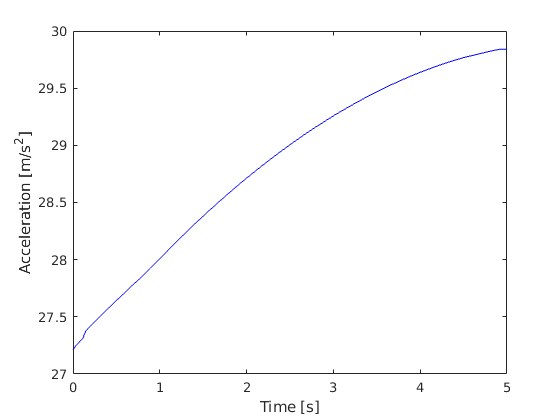

    if length (acc) > lt
        la=length(acc);
        acc(lt+1:la)=[];
    end
% plot results   
figure (1)
plot (T,acc,'b-')
ylabel ('Acceleration [m/s^2]')
xlabel ('Time [s]')

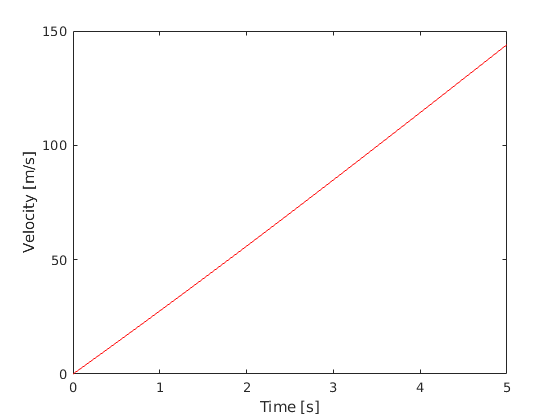

figure (2)
plot (T,Y(:,1),'r-')
ylabel ('Velocity [m/s]')
xlabel ('Time [s]')

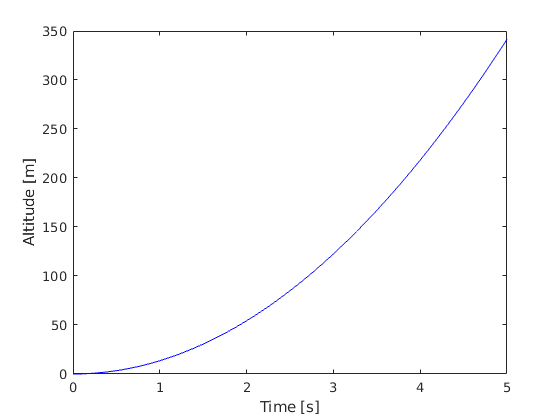

figure (3)
plot (T,Y(:,2)-r0,'b-')
ylabel ('Altitude [m]')
xlabel ('Time [s]')

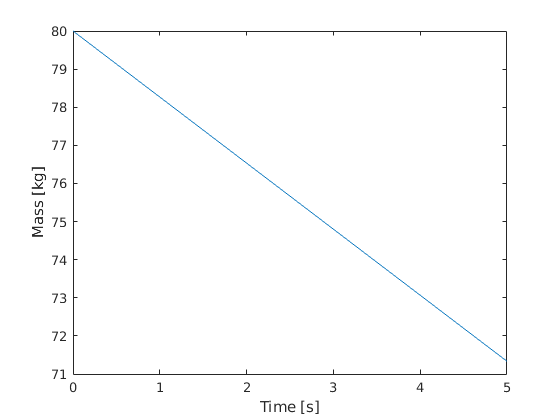

figure (4)
plot (T,Y(:,3))
ylabel ('Mass [kg]')
xlabel ('Time [s]')

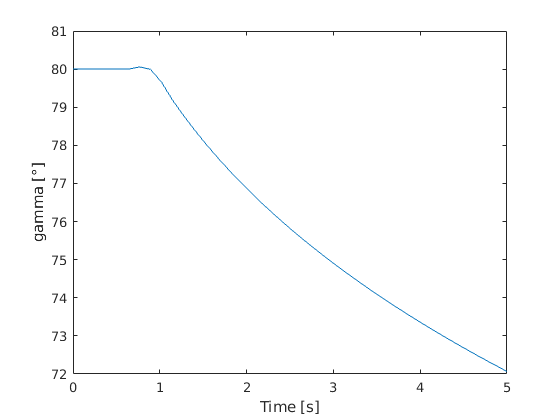

figure (5)
plot (T,Y(:,4)*180/pi)
ylabel ('gamma [°]')
xlabel ('Time [s]')